Problem (3)

Student 1: Saachi Tamboli

Student 2: Brett Luthern

% Parameters

zetaP = 350; %km - perigee altitude
rp = 6371 + zetaP; % perigee radius
e = 0.1;
Omega = 195 * pi/180; %rad
i = 54 * pi/180; %rad
w = 235 * pi/180; %rad
ta = 20 * pi/180; %rad
muE = 3.986e5;
rE = 6371;

N = 30;
sigma_v = 0.1; % km/s  (= 100 m/s)
mu_bc = log(20);
sigma_bc = 0.5;

Part A:

a = rp/(1-e);
[r0_sat, v0_sat] = coe2rv(a, e, Omega, i, w, ta, muE);
r0_sat = r0_sat(:);  v0_sat = v0_sat(:);
% a) Code function [v, bc] = explosion(mu_v, sigma_v, mu_bc, sigma_bc)

function [v, bc] = explosion(mu_v, sigma_v, mu_bc, sigma_bc)
    N  = 30;
    v  = mu_v(:) + sigma_v * randn(3, N);
    bc = lognrnd(mu_bc, sigma_bc, [1, N]);
end

rng(1);
[v0_debris, bc] = explosion(v0, 0.1, mu_bc, sigma_bc);

N = 30;
V = zeros(3, N);

r0_debris = repmat(r0(:), 1, N); % map all 30 with the same position

Part B:

% b) implement a function ap = drag_acceleration(zeta, v, bc)


function ap = drag_acceleration(zeta, v, bc)
% Isothermal atmosphere drag. v in km/s, bc in kg/m², returns km/s².
    H     = 50;        % scale height [km]
    rho0  = 1e-8;      % density at zeta0 [kg/m³]
    zeta0 = 100;       % reference altitude [km]
    if zeta < zeta0
        ap = nan(3,1);
        return
    end
    rho = rho0 * exp(-(zeta - zeta0) / H);    % kg/m^3
 
    % Unit conversion to km/m^3 multiply by 1000 to get km/s².
    ap = -0.5 * rho * norm(v) * v(:) / bc * 1000;
end

Part C:

function ap = J2_acceleration(r)
    J2  = 0.00108263;
    muE = 3.986e5;
    rE  = 6371;
    x = r(1);  y = r(2);  z = r(3);
    rmag = norm(r);
    rz2  = (z/rmag)^2;
    factor = -1.5 * J2 * muE * rE^2 / rmag^5;
    ap = factor * [ x*(1 - 5*rz2);
                    y*(1 - 5*rz2);
                    z*(3 - 5*rz2) ];
end

ap = J2_acceleration(r0);

Part D:

function [r, v] = cowell(r0, v0, bc, t, flag_drag, flag_J2)
    muE = 3.986e5;
    rE  = 6371;
    N   = size(r0, 2);
    M   = numel(t);
    r   = nan(3, N, M);
    v   = nan(3, N, M);

    opts = odeset('RelTol', 1e-9, 'AbsTol', 1e-10, ...
                  'Events', @(tt,y) reentry_event(tt,y,rE));

    for k = 1:N
        y0 = [r0(:,k); v0(:,k)];
        try
            [Tsol, Y, te, ~, ~] = ode45( ...
                @(tt,y) eom(tt,y,bc(k),muE,rE,flag_drag,flag_J2), ...
                t, y0, opts);
        catch
            continue
        end

        % If the event triggered, ode45 returns Tsol with rows up to and
        % including the event time. Some of those Tsol rows may NOT match
        % entries of t (the event row is extra). We only keep rows that
        % correspond to entries of our requested t-grid.
        % Strategy: match Tsol values back to t with a tolerance.
        nT = numel(t);
        for idx = 1:size(Y,1)
            % Find which requested time this row matches (if any)
            [dt_min, j] = min(abs(t - Tsol(idx)));
            if dt_min < 1e-6 * max(abs(t(end)), 1)
                r(:, k, j) = Y(idx, 1:3).';
                v(:, k, j) = Y(idx, 4:6).';
            end
        end
    end
end

function dy = eom(~, y, bc_k, muE, rE, flag_drag, flag_J2)
    rvec = y(1:3);  vvec = y(4:6);
    rmag = norm(rvec);
    accel = -muE / rmag^3 * rvec;
    if flag_J2
        accel = accel + J2_acceleration(rvec);
    end
    if flag_drag
        zeta = rmag - rE;
        if zeta >= 100
            ad = drag_acceleration(zeta, vvec, bc_k);
            if ~any(isnan(ad))
                accel = accel + ad;
            end
        end
        % If below 100 km, don't add drag — Events function will stop us
    end
    dy = [vvec; accel];
end

function [value, isterminal, direction] = reentry_event(~, y, rE)
% Stops integration when altitude drops to 100 km
    rmag = norm(y(1:3));
    value = (rmag - rE) - 100;     % zero when altitude = 100 km
    isterminal = 1;                % stop on detection
    direction  = -1;               % only when descending
end

Part E:


=== Case 1: No perturbations ===


Propagating 30 pieces over 26 epochs...


  Cowell: 139.88 s


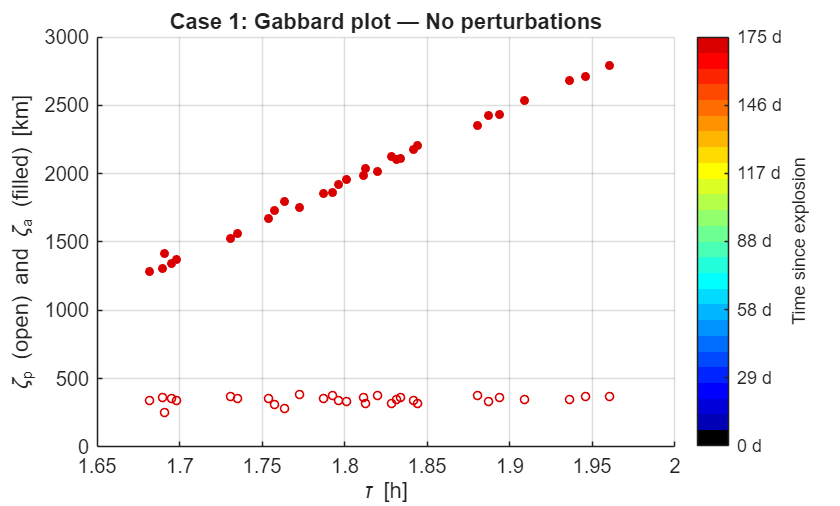

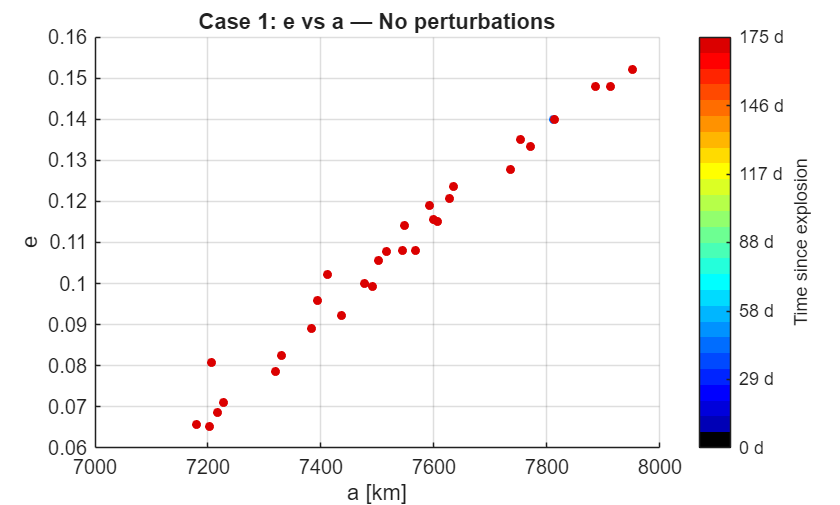

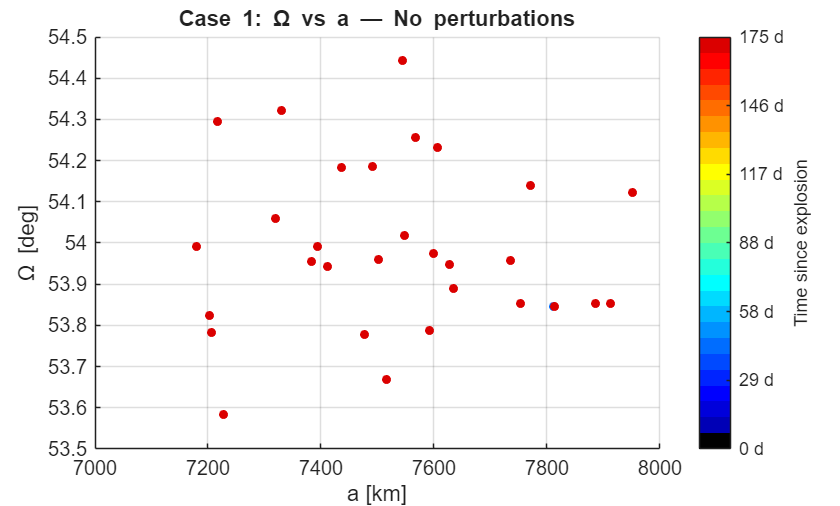


=== Case 2: Drag only ===


Propagating 30 pieces over 26 epochs...


  Cowell: 139.79 s


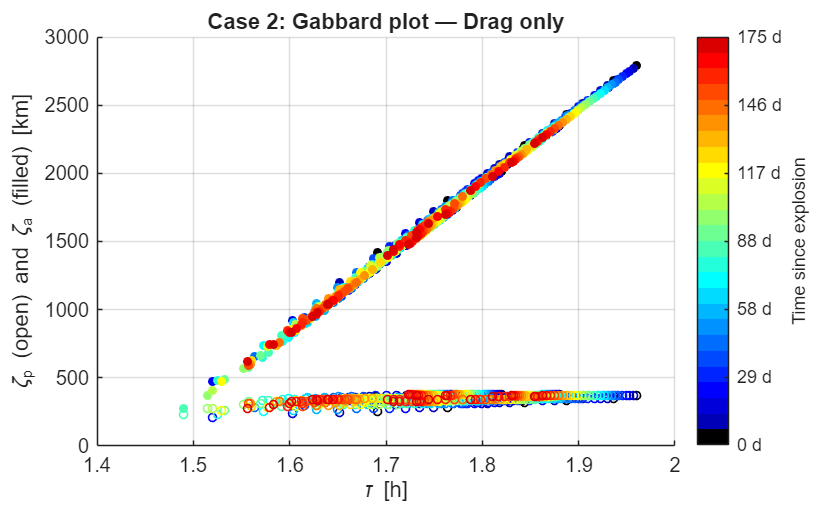

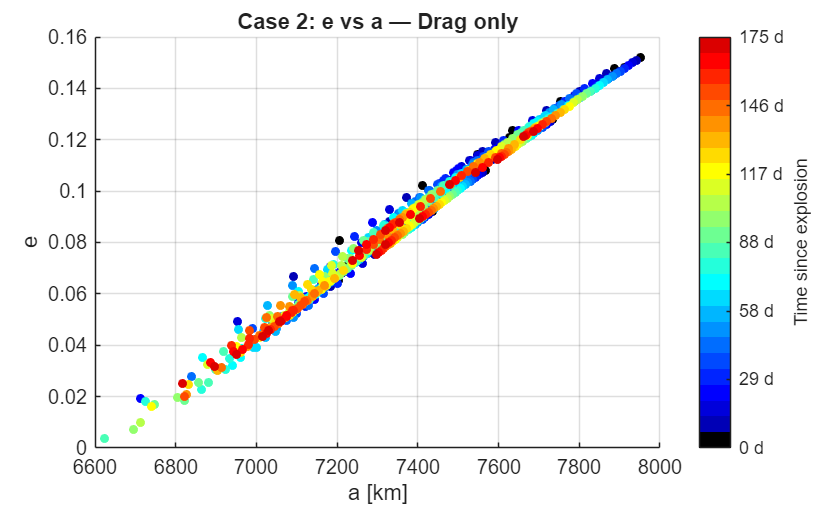

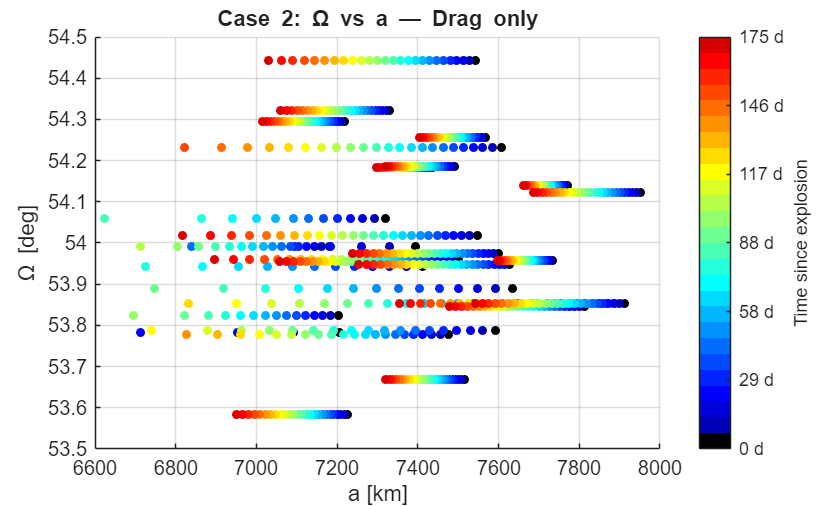


=== Case 3: Drag + J2 ===


Propagating 30 pieces over 26 epochs...


  Cowell: 165.15 s


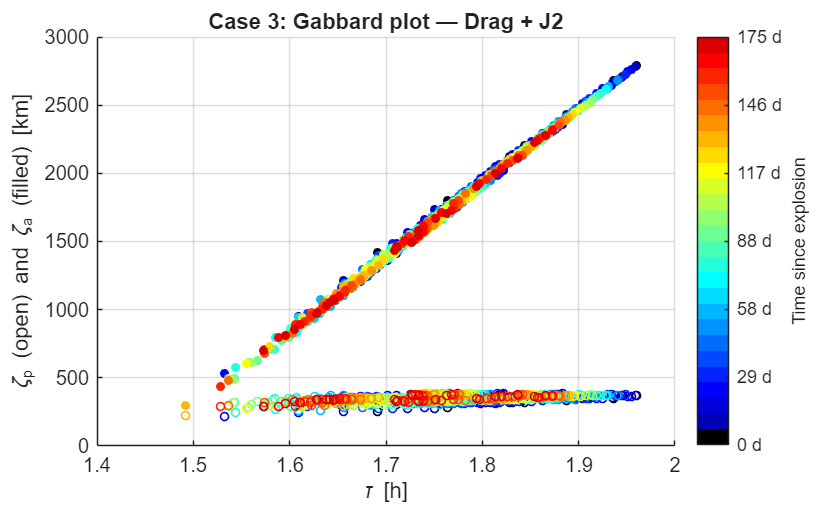

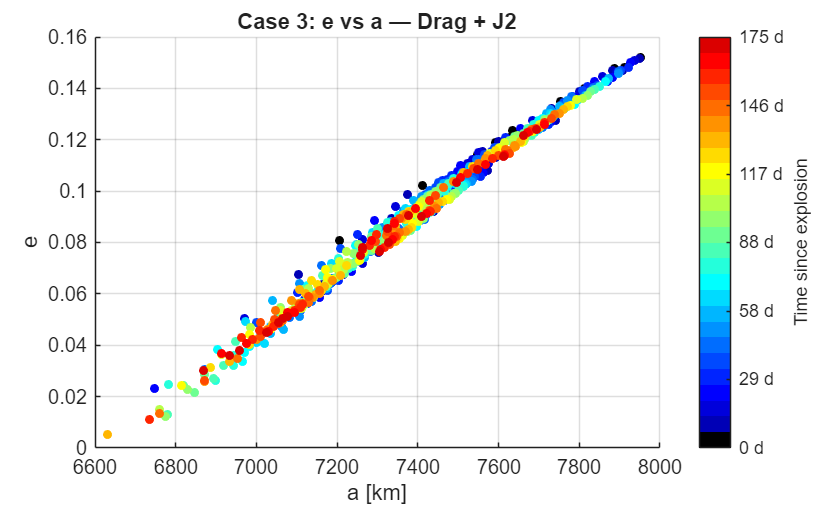

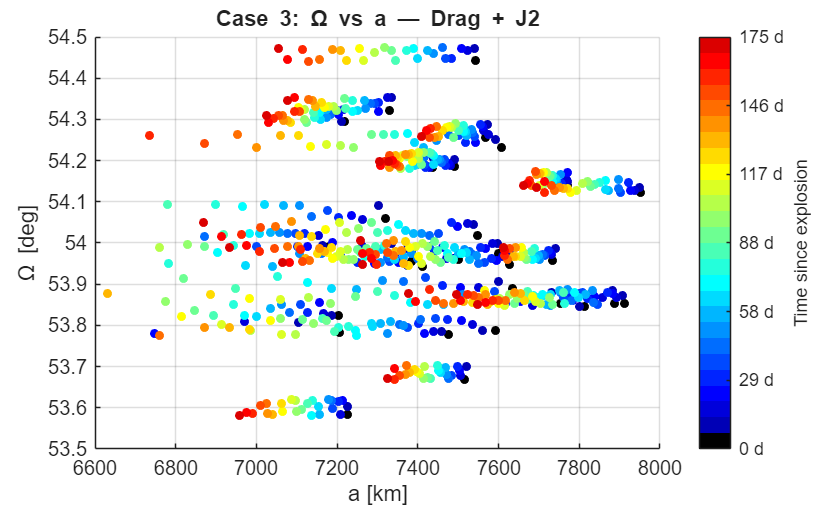

dt_days = 7;
t_days  = 0:dt_days:180;     % 0, 7, 14, …, 180  (27 epochs)
t_sec   = t_days * 86400;
M = numel(t_sec);

case_titles = {'No perturbations', 'Drag only', 'Drag + J2'};
case_flags  = {[false false], [true false], [true true]};
 
for c = 1:3
    flag_drag = case_flags{c}(1);
    flag_J2   = case_flags{c}(2);
 
    fprintf('\n=== Case %d: %s ===\n', c, case_titles{c});
 
    % FIX: reseed RNG before each simulation so all 3 cases use the same cloud
    rng(1);
    [v_dispersion, bc] = explosion(v0_sat, sigma_v, mu_bc, sigma_bc);
    v0_debris = v_dispersion;                   % each column is one piece's v
    r0_debris = repmat(r0_sat, 1, N);            % FIX: same r0 for all pieces
 
    fprintf('Propagating %d pieces over %d epochs...\n', N, M);
    tic;
    [r_traj, v_traj] = cowell(r0_debris, v0_debris, bc, t_sec, flag_drag, flag_J2);
    fprintf('  Cowell: %.2f s\n', toc);
 
    % Extract orbital elements at each epoch
    a_hist     = nan(N, M);
    e_hist     = nan(N, M);
    Omega_hist = nan(N, M);
    zp_hist    = nan(N, M);
    za_hist    = nan(N, M);
    tau_hist   = nan(N, M);
 
    for k = 1:N
        for m = 1:M
            rk = r_traj(:,k,m);
            vk = v_traj(:,k,m);
            if any(isnan(rk)) || any(isnan(vk));  continue;  end
            [aa, ee, OO, ~, ~, ~] = rv2coe(rk, vk);
            if ~isfinite(aa) || aa <= 0 || ee >= 1;  continue;  end
            a_hist(k,m)     = aa;
            e_hist(k,m)     = ee;
            Omega_hist(k,m) = OO;
            zp_hist(k,m)    = aa*(1-ee) - rE;
            za_hist(k,m)    = aa*(1+ee) - rE;
            tau_hist(k,m)   = 2*pi*sqrt(aa^3/muE) / 3600;
        end
    end
 
    % ── Plotting (all 3 figures per case) ────────────────────────────
    % Color map: t=0 black, then jet from blue (early) to red (late)
    cmap = [0 0 0; jet(M-1)];
 
    % Gabbard plot — perigee (○) and apogee (●) altitude vs period
    figure('Name', sprintf('Case %d Gabbard', c), 'Color', 'w');
    hold on; grid on;
   
    for m = 1:M
        col = cmap(m,:);
        valid = isfinite(tau_hist(:,m));
        if ~any(valid); continue; end          % skip empty epochs
        h1 = plot(tau_hist(valid,m), zp_hist(valid,m), 'o', ...
        'MarkerEdgeColor', col, 'MarkerSize', 4, 'LineWidth', 0.8);
        plot(tau_hist(valid,m), za_hist(valid,m), 'o', ...
        'MarkerFaceColor', col, 'MarkerEdgeColor', col, 'MarkerSize', 4);
        if ~isempty(h1)
            leg_handles(m) = h1(1);            % h1 may be vector — take first
        end
    end
    xlabel('\tau [h]'); ylabel('\zeta_p (open) and \zeta_a (filled) [km]');
    title(sprintf('Case %d: Gabbard plot — %s', c, case_titles{c}));
    add_time_colorbar(t_days, cmap);
 
    % e vs a
    figure('Name', sprintf('Case %d e vs a', c), 'Color', 'w');
    hold on; grid on;
    for m = 1:M
        col = cmap(m,:);
        valid = isfinite(a_hist(:,m));
        plot(a_hist(valid,m), e_hist(valid,m), 'o', ...
            'MarkerFaceColor', col, 'MarkerEdgeColor', col, 'MarkerSize', 4);
    end
    xlabel('a [km]'); ylabel('e');
    title(sprintf('Case %d: e vs a — %s', c, case_titles{c}));
    add_time_colorbar(t_days, cmap);
 
    % Omega vs a
    figure('Name', sprintf('Case %d Omega vs a', c), 'Color', 'w');
    hold on; grid on;
    for m = 1:M
        col = cmap(m,:);
        valid = isfinite(a_hist(:,m));
        plot(a_hist(valid,m), rad2deg(Omega_hist(valid,m)), 'o', ...
            'MarkerFaceColor', col, 'MarkerEdgeColor', col, 'MarkerSize', 4);
    end
    xlabel('a [km]'); ylabel('\Omega [deg]');
    title(sprintf('Case %d: \\Omega vs a — %s', c, case_titles{c}));
    add_time_colorbar(t_days, cmap);
end

% color bar function for loop
function add_time_colorbar(t_days, cmap)
% Add a colorbar showing the time of each snapshot.
    colormap(cmap);
    cb = colorbar;
    M  = numel(t_days);
    nticks = min(7, M);
    cb.Ticks = linspace(0, 1, nticks);
    cb.TickLabels = arrayfun(@(x) sprintf('%d d', round(x)), ...
        linspace(t_days(1), t_days(end), nticks), 'UniformOutput', false);
    cb.Label.String = 'Time since explosion';
end